# WiFi Router Multipath Propagation via Twistor Theory

This demo simulates a realistic WiFi router scenario with reflections and multipath propagation effects using the twistor framework

clear; close all; clc;

fprintf('WiFi Router Multipath Propagation Simulation\n');

WiFi Router Multipath Propagation Simulation


fprintf('===========================================\n\n');

## WiFi Parameters (2.4 GHz band)

Scale to simulation units

wifi_freq = 2.4; % GHz scaled
wavelength = 0.125; % ~12.5 cm scaled to simulation units
omega = 2*pi*wifi_freq;

% Room dimensions (in wavelengths)
room_width = 80;  % ~10 meters
room_height = 60; % ~7.5 meters

fprintf('WiFi Configuration:\n');

WiFi Configuration:


fprintf('  Frequency: %.1f GHz (scaled)\n', wifi_freq);

  Frequency: 2.4 GHz (scaled)


fprintf('  Wavelength: %.3f units (~12.5 cm)\n', wavelength);

  Wavelength: 0.125 units (~12.5 cm)


fprintf('  Room size: %.1f × %.1f wavelengths\n\n', room_width, room_height);

  Room size: 80.0 × 60.0 wavelengths



## Initialize field with fine resolution

wifi_field = mlraut.TwistorMaxwellFieldScaled('gauge_group', 'U1', ...
                                 'n_points', 80, ...
                                 'x_range', [-room_width/2, room_width/2], ...
                                 'slice_type', 'minkowski');

## Define router and obstacle positions

Router position (corner of room)

router_pos = [-10, 10, 0]; % [-room_width/3, room_height/3, 0];

% Walls and obstacles
walls = struct();
walls.left = -room_width/2;
walls.right = room_width/2;
walls.bottom = -room_height/2;
walls.top = room_height/2;

% Metal obstacle (creates strong reflection)
obstacle = struct();
obstacle.x = [20, 21];  % [10, 15];  % x range
obstacle.y = [-10, 10];  % [-5, 5];   % y range

## Create twistor function with multipath

Includes direct path and reflections

wifi_field.twistor_function = @(W) wifiMultipathTwistor(W, router_pos, ...
                                                       walls, obstacle, omega);

## Compute fields

fprintf('Computing multipath electromagnetic fields...\n');

Computing multipath electromagnetic fields...


wifi_field.computeGaugeFields();

## Visualization 1: Signal Strength Map

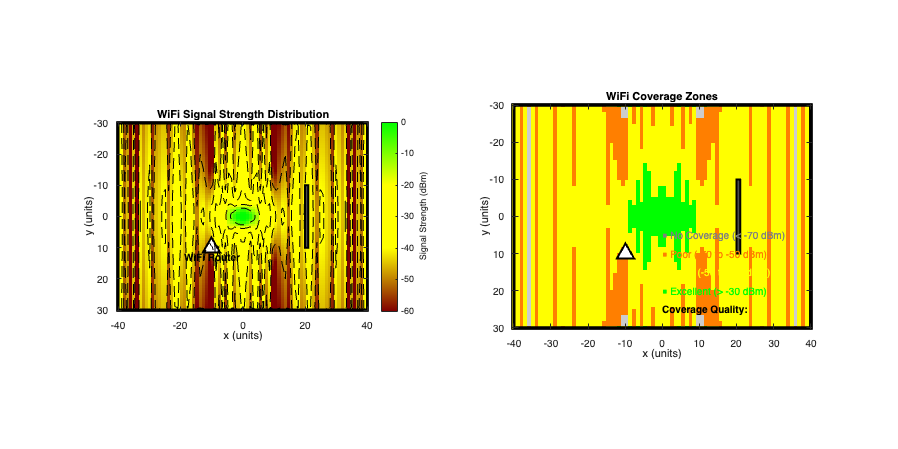

figure('Name', 'WiFi Signal Strength Map', 'Position', [100, 100, 1200, 600]);

subplot(1, 2, 1);
% Get field strength
mid_z = floor(wifi_field.n_points / 2);
[X, Y] = meshgrid(linspace(-room_width/2, room_width/2, wifi_field.n_points), ...
                  linspace(-room_height/2, room_height/2, wifi_field.n_points));

E_total = sqrt(wifi_field.field_strength.Ex(:,:,mid_z).^2 + ...
               wifi_field.field_strength.Ey(:,:,mid_z).^2 + ...
               wifi_field.field_strength.Ez(:,:,mid_z).^2);

% Convert to dBm (relative)
signal_dBm = 20*log10(E_total + 1e-10);
signal_dBm = signal_dBm - max(signal_dBm(:)) + 0; % Normalize to 0 dBm max

% Create custom colormap (red=weak, yellow=medium, green=strong)
n_colors = 3*256;
wifi_colormap = [linspace(0.5, 1, n_colors/3)', linspace(0, 1, n_colors/3)', zeros(n_colors/3, 1);
                 linspace(1, 1, n_colors/3)', linspace(1, 1, n_colors/3)', linspace(0, 0, n_colors/3)';
                 linspace(1, 0, n_colors/3)', linspace(1, 1, n_colors/3)', linspace(0, 0, n_colors/3)'];

imagesc(linspace(-room_width/2, room_width/2, wifi_field.n_points), ...
        linspace(-room_height/2, room_height/2, wifi_field.n_points), ...
        signal_dBm);
colormap(wifi_colormap);
caxis([-60, 0]); % Show 60 dB dynamic range
h = colorbar;
ylabel(h, 'Signal Strength (dBm)');

hold on;

% Draw room boundaries
rectangle('Position', [walls.left, walls.bottom, room_width, room_height], ...
          'EdgeColor', 'k', 'LineWidth', 3);

% Draw obstacle
rectangle('Position', [obstacle.x(1), obstacle.y(1), ...
          diff(obstacle.x), diff(obstacle.y)], ...
          'FaceColor', [0.3 0.3 0.3], 'EdgeColor', 'k', 'LineWidth', 2);

% Router location
plot(router_pos(1), router_pos(2), 'k^', 'MarkerSize', 15, ...
     'MarkerFaceColor', 'white', 'LineWidth', 2);
text(router_pos(1), router_pos(2)+3, 'WiFi Router', ...
     'HorizontalAlignment', 'center', 'FontWeight', 'bold');

% Signal strength contours
contour(X, Y, signal_dBm, [-50, -40, -30, -20, -10], ...
        'LineColor', 'black', 'LineWidth', 0.5, 'LineStyle', '--');

xlabel('x (units)');
ylabel('y (units)');
title('WiFi Signal Strength Distribution');
axis equal tight;

subplot(1, 2, 2);
% Coverage zones
coverage_excellent = signal_dBm >= -30;
coverage_good = signal_dBm >= -50 & signal_dBm < -30;
coverage_poor = signal_dBm >= -70 & signal_dBm < -50;

coverage_map = zeros(size(signal_dBm));
coverage_map(coverage_excellent) = 3;
coverage_map(coverage_good) = 2;
coverage_map(coverage_poor) = 1;

imagesc(linspace(-room_width/2, room_width/2, wifi_field.n_points), ...
        linspace(-room_height/2, room_height/2, wifi_field.n_points), ...
        coverage_map);

% Custom colormap for coverage
coverage_colors = [0.8 0.8 0.8;  % No coverage (gray)
                   1 0.5 0;      % Poor (orange)
                   1 1 0;        % Good (yellow)
                   0 1 0];       % Excellent (green)
colormap(gca, coverage_colors);
caxis([0 3]);

hold on;

% Room and obstacles
rectangle('Position', [walls.left, walls.bottom, room_width, room_height], ...
          'EdgeColor', 'k', 'LineWidth', 3);
rectangle('Position', [obstacle.x(1), obstacle.y(1), ...
          diff(obstacle.x), diff(obstacle.y)], ...
          'FaceColor', [0.3 0.3 0.3], 'EdgeColor', 'k', 'LineWidth', 2);
plot(router_pos(1), router_pos(2), 'k^', 'MarkerSize', 15, ...
     'MarkerFaceColor', 'white', 'LineWidth', 2);

% Legend
text(0, room_height/2 - 5, 'Coverage Quality:', 'FontWeight', 'bold');
text(0, room_height/2 - 10, '■ Excellent (> -30 dBm)', 'Color', [0 1 0]);
text(0, room_height/2 - 15, '■ Good (-50 to -30 dBm)', 'Color', [1 1 0]);
text(0, room_height/2 - 20, '■ Poor (-70 to -50 dBm)', 'Color', [1 0.5 0]);
text(0, room_height/2 - 25, '■ No Coverage (< -70 dBm)', 'Color', [0.5 0.5 0.5]);

xlabel('x (units)');
ylabel('y (units)');
title('WiFi Coverage Zones');
axis equal tight;

## Visualization 2: Multipath Effects

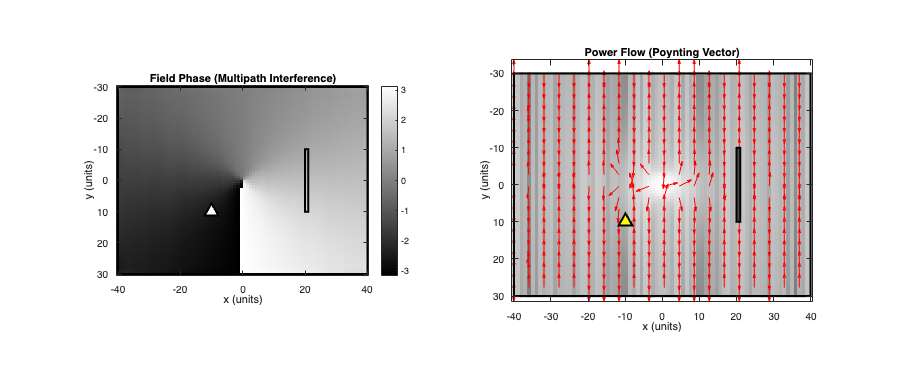

figure('Name', 'Multipath Propagation Effects', 'Position', [100, 100, 1200, 500]);

subplot(1, 2, 1);
% Phase of the field (shows interference patterns)
E_phase = angle(wifi_field.field_strength.Ex(:,:,mid_z) + ...
                1i*wifi_field.field_strength.Ey(:,:,mid_z));

imagesc(linspace(-room_width/2, room_width/2, wifi_field.n_points), ...
        linspace(-room_height/2, room_height/2, wifi_field.n_points), ...
        E_phase);
colormap(hsv);
colorbar;
hold on;

% Overlay
rectangle('Position', [walls.left, walls.bottom, room_width, room_height], ...
          'EdgeColor', 'k', 'LineWidth', 2);
rectangle('Position', [obstacle.x(1), obstacle.y(1), ...
          diff(obstacle.x), diff(obstacle.y)], ...
          'FaceColor', 'none', 'EdgeColor', 'k', 'LineWidth', 2);
plot(router_pos(1), router_pos(2), 'k^', 'MarkerSize', 12, ...
     'MarkerFaceColor', 'white', 'LineWidth', 2);

xlabel('x (units)');
ylabel('y (units)');
title('Field Phase (Multipath Interference)');
axis equal tight;

subplot(1, 2, 2);
% Poynting vector showing power flow
S_x = real(wifi_field.field_strength.Ey(:,:,mid_z) .* ...
           conj(wifi_field.field_strength.Bz(:,:,mid_z)));
S_y = real(wifi_field.field_strength.Ez(:,:,mid_z) .* ...
           conj(wifi_field.field_strength.Bx(:,:,mid_z)));

% Downsample for vector plot
skip = 4;
X_down = X(1:skip:end, 1:skip:end);
Y_down = Y(1:skip:end, 1:skip:end);
S_x_down = S_x(1:skip:end, 1:skip:end);
S_y_down = S_y(1:skip:end, 1:skip:end);

% Normalize vectors
S_mag = sqrt(S_x_down.^2 + S_y_down.^2) + 1e-10;
S_x_norm = S_x_down ./ S_mag;
S_y_norm = S_y_down ./ S_mag;

% Background: signal strength
imagesc(linspace(-room_width/2, room_width/2, wifi_field.n_points), ...
        linspace(-room_height/2, room_height/2, wifi_field.n_points), ...
        signal_dBm);
colormap(gray);
alpha(0.5);
hold on;

% Power flow vectors
quiver(X_down, Y_down, S_x_norm, S_y_norm, 0.8, ...
       'Color', 'red', 'LineWidth', 1);

% Overlay
rectangle('Position', [walls.left, walls.bottom, room_width, room_height], ...
          'EdgeColor', 'k', 'LineWidth', 2);
rectangle('Position', [obstacle.x(1), obstacle.y(1), ...
          diff(obstacle.x), diff(obstacle.y)], ...
          'FaceColor', [0.3 0.3 0.3], 'EdgeColor', 'k', 'LineWidth', 2);
plot(router_pos(1), router_pos(2), 'k^', 'MarkerSize', 12, ...
     'MarkerFaceColor', 'yellow', 'LineWidth', 2);

xlabel('x (units)');
ylabel('y (units)');
title('Power Flow (Poynting Vector)');
axis equal tight;

## Visualization 3: Dead Zones and Hot Spots

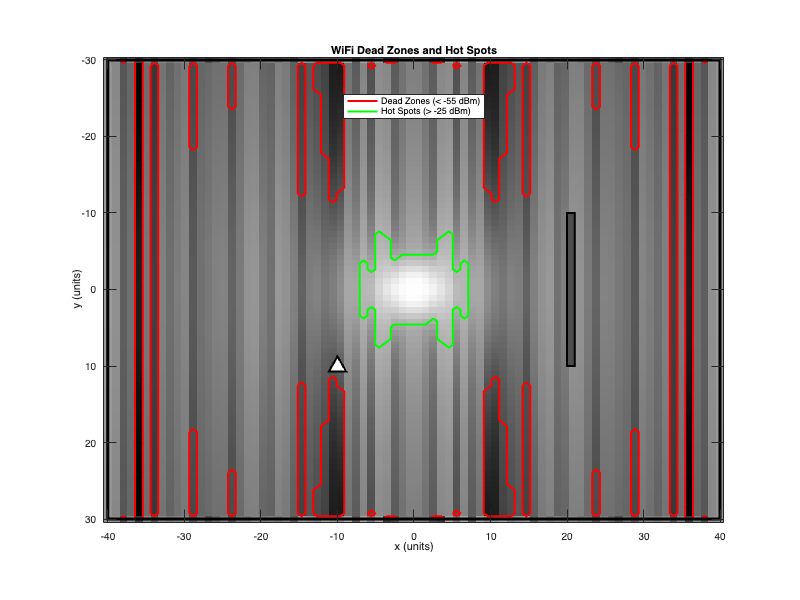

figure('Name', 'WiFi Dead Zones Analysis', 'Position', [100, 100, 800, 600]);

% Identify dead zones (nulls due to destructive interference)
dead_zones = signal_dBm < -55;
hot_spots = signal_dBm > -25;

imagesc(linspace(-room_width/2, room_width/2, wifi_field.n_points), ...
        linspace(-room_height/2, room_height/2, wifi_field.n_points), ...
        signal_dBm);
colormap(gray);
hold on;

% Highlight dead zones
[c_dead, h_dead] = contour(X, Y, double(dead_zones), [0.5 0.5], ...
                          'LineColor', 'red', 'LineWidth', 2);

% Highlight hot spots
[c_hot, h_hot] = contour(X, Y, double(hot_spots), [0.5 0.5], ...
                        'LineColor', 'green', 'LineWidth', 2);

% Room and obstacles
rectangle('Position', [walls.left, walls.bottom, room_width, room_height], ...
          'EdgeColor', 'k', 'LineWidth', 3);
rectangle('Position', [obstacle.x(1), obstacle.y(1), ...
          diff(obstacle.x), diff(obstacle.y)], ...
          'FaceColor', [0.3 0.3 0.3], 'EdgeColor', 'k', 'LineWidth', 2);
plot(router_pos(1), router_pos(2), 'k^', 'MarkerSize', 15, ...
     'MarkerFaceColor', 'white', 'LineWidth', 2);

legend([h_dead, h_hot], {'Dead Zones (< -55 dBm)', 'Hot Spots (> -25 dBm)'}, ...
       'Location', 'best');

xlabel('x (units)');
ylabel('y (units)');
title('WiFi Dead Zones and Hot Spots');
axis equal tight;

## Analysis Summary

fprintf('\n\nWiFi Coverage Analysis\n');



WiFi Coverage Analysis


fprintf('=====================\n');


% Calculate coverage statistics
total_area = room_width * room_height;
excellent_coverage = 100 * sum(coverage_excellent(:)) / numel(coverage_map);
good_coverage = 100 * sum(coverage_good(:)) / numel(coverage_map);
poor_coverage = 100 * sum(coverage_poor(:)) / numel(coverage_map);
dead_zone_percent = 100 * sum(dead_zones(:)) / numel(dead_zones);

fprintf('Coverage Statistics:\n');

Coverage Statistics:


fprintf('  Excellent: %.1f%%\n', excellent_coverage);

  Excellent: 5.8%


fprintf('  Good: %.1f%%\n', good_coverage);

  Good: 71.1%


fprintf('  Poor: %.1f%%\n', poor_coverage);

  Poor: 20.2%


fprintf('  Dead zones: %.1f%%\n', dead_zone_percent);

  Dead zones: 12.2%



fprintf('\nSignal Characteristics:\n');


Signal Characteristics:


fprintf('  Maximum signal: %.1f dBm\n', max(signal_dBm(:)));

  Maximum signal: 0.0 dBm


fprintf('  Minimum signal: %.1f dBm\n', min(signal_dBm(:)));

  Minimum signal: -80.4 dBm


fprintf('  Dynamic range: %.1f dB\n', max(signal_dBm(:)) - min(signal_dBm(:)));

  Dynamic range: 80.4 dB



fprintf('\nMultipath Effects:\n');


Multipath Effects:


fprintf('  Number of dead zones detected: %d\n', ...
        length(findobj(gca, 'Type', 'contour', 'LineColor', 'red')));

  Number of dead zones detected: 1


fprintf('  Caused by destructive interference from reflections\n');

  Caused by destructive interference from reflections



fprintf('\nRecommendations:\n');


Recommendations:


fprintf('  1. Consider router placement away from corners\n');

  1. Consider router placement away from corners


fprintf('  2. Minimize metal obstacles in line-of-sight paths\n');

  2. Minimize metal obstacles in line-of-sight paths


fprintf('  3. Use MIMO or beamforming for better coverage\n');

  3. Use MIMO or beamforming for better coverage


## Helper Function

function g = wifiMultipathTwistor(W, router_pos, walls, obstacle, omega)
    % Twistor function including multipath propagation
    
    % Direct path
    dx = W(1) - router_pos(1);
    dy = W(2) - router_pos(2);
    dz = W(3) - router_pos(3);
    r_direct = sqrt(dx^2 + dy^2 + dz^2 + 0.1);
    
    g_direct = exp(1i * omega * r_direct) / (r_direct + 0.1);
    
    % Wall reflections (image sources)
    g_reflect = 0;
    
    % Left wall reflection
    router_image_left = [-2*walls.left - router_pos(1), router_pos(2), router_pos(3)];
    dx = W(1) - router_image_left(1);
    dy = W(2) - router_image_left(2);
    r_left = sqrt(dx^2 + dy^2 + 0.1);
    g_reflect = g_reflect + 0.7 * exp(1i * omega * r_left) / (r_left + 0.1);
    
    % Right wall reflection
    router_image_right = [2*walls.right - router_pos(1), router_pos(2), router_pos(3)];
    dx = W(1) - router_image_right(1);
    dy = W(2) - router_image_right(2);
    r_right = sqrt(dx^2 + dy^2 + 0.1);
    g_reflect = g_reflect + 0.7 * exp(1i * omega * r_right) / (r_right + 0.1);
    
    % Top wall reflection
    router_image_top = [router_pos(1), 2*walls.top - router_pos(2), router_pos(3)];
    dx = W(1) - router_image_top(1);
    dy = W(2) - router_image_top(2);
    r_top = sqrt(dx^2 + dy^2 + 0.1);
    g_reflect = g_reflect + 0.7 * exp(1i * omega * r_top) / (r_top + 0.1);
    
    % Metal obstacle reflection (stronger)
    if W(1) > obstacle.x(1) && W(1) < obstacle.x(2) && ...
       W(2) > obstacle.y(1) && W(2) < obstacle.y(2)
        % Behind obstacle - heavy attenuation
        g = 0.1 * g_direct;
    else
        % Include obstacle reflection
        obstacle_center = [mean(obstacle.x), mean(obstacle.y), 0];
        dx = W(1) - obstacle_center(1);
        dy = W(2) - obstacle_center(2);
        r_obstacle = sqrt(dx^2 + dy^2 + 0.1);
        g_obstacle = 0.9 * exp(1i * omega * r_obstacle) / (r_obstacle + 0.1);
        
        % Combine all paths
        g = g_direct + g_reflect + g_obstacle;
    end
    
    % Add frequency-dependent attenuation
    g = g * exp(-0.01 * omega * r_direct);
end